# **Measurements of Nonlinear Dynamics of a Brake-Reuß Beam**

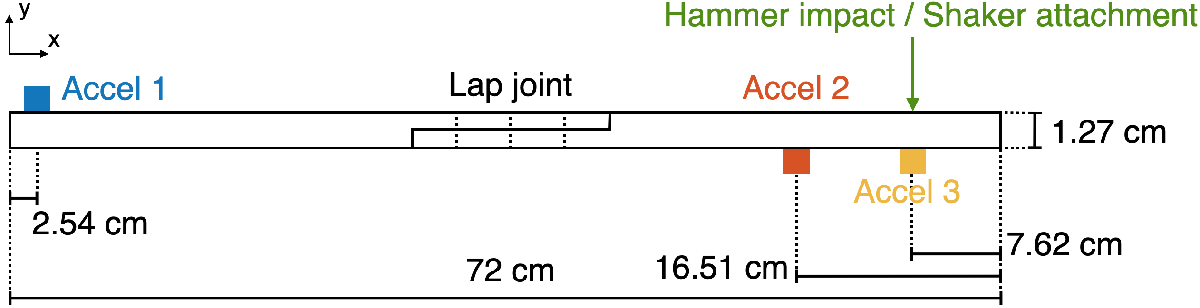

**Figure 1**: Structure and experimental setup.

We present a dataset of measurements of the vibrations of a free-free Brake-Reuß beam, illustrated in Fig. 1. The vibrations are measured along the y-axis. For an accurate description of the experiments and the identification results please refer to the papers:

W. Chen, D. Jana, A. Singh, M. Jin, M. Cenedese, G. Kosova, M. W. R. Brake, C. W. Schwingshackl, S. Nagarajaiah, K. Moore, and J. P. Noël. Measurement and identification of the nonlinear dynamics of a jointed structure using full-field data; Part I - Measurement of nonlinear dynamics. *Under revision*, 2021. 

M. Jin, G. Kosova, M. Cenedese, W. Chen, D. Jana, A. Singh, M. W. R. Brake, C. W. Schwingshackl, S. Nagarajaiah, K. Moore, and J. P. Noël. Measurement and identification of the nonlinear dynamics of a jointed structure using full-field data; Part II - Nonlinear system identification. *Under revision*, 2021. 

clear 
close all
format shortg

fontname = 'helvetica';
fontsize = 16;

## Accelerometer Data

### Hammer Impact Testing

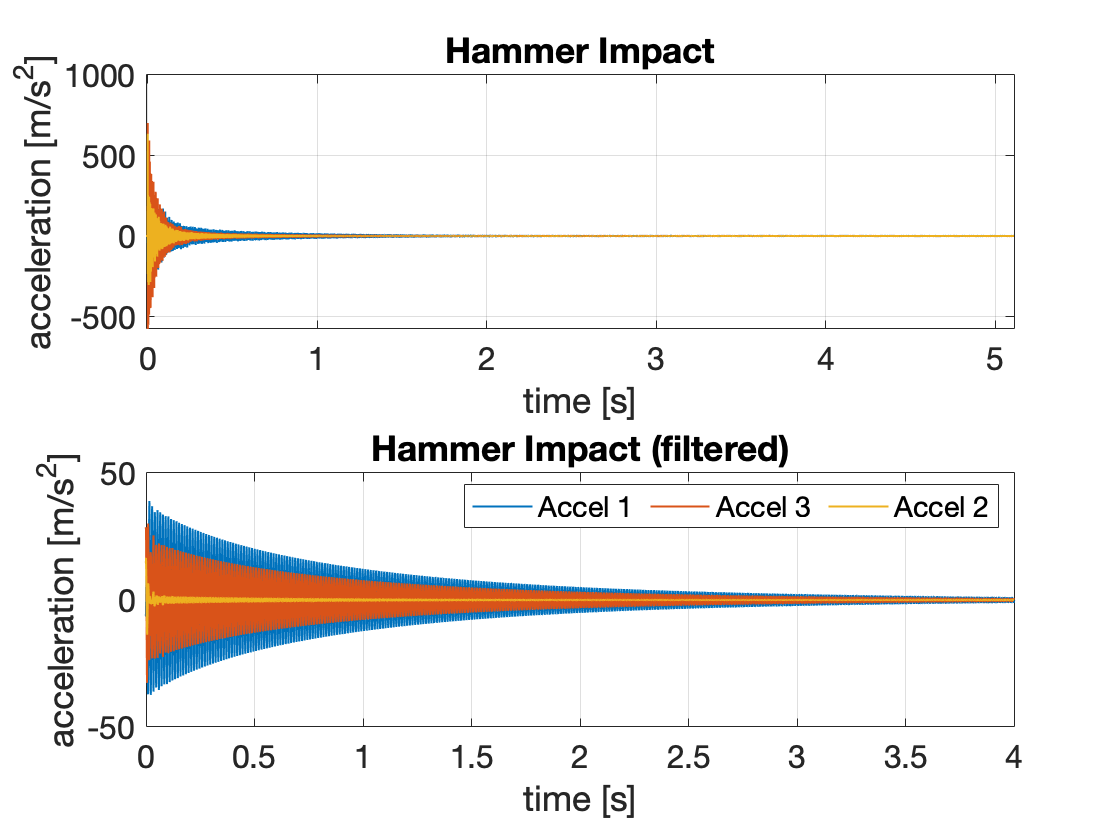

load HammerImpact.mat % Peak force of 300N

figure;
subplot(211); hold on; grid on; box on; title('Hammer Impact')
plot(HIdata.time,HIdata.acc1,'Linewidth',1,'DisplayName','Accel 1')
plot(HIdata.time,HIdata.acc3,'Linewidth',1,'DisplayName','Accel 3')
plot(HIdata.time,HIdata.acc2,'Linewidth',1,'DisplayName','Accel 2')
xlabel('time [s]')
ylabel('acceleration [m/s^2]')
set(gca,'fontname',fontname)
set(gca,'fontsize',fontsize)
xlim([HIdata.time(1) HIdata.time(end) ])
subplot(212); hold on; grid on; box on; title('Hammer Impact (filtered)')
fpass = [60 120];
filt_acc1 = bandpass(HIdata.acc1,fpass,1/(HIdata.time(2)-HIdata.time(1)));
filt_acc2 = bandpass(HIdata.acc2,fpass,1/(HIdata.time(2)-HIdata.time(1)));
filt_acc3 = bandpass(HIdata.acc3,fpass,1/(HIdata.time(2)-HIdata.time(1)));
plot(HIdata.time,filt_acc1,'Linewidth',1,'DisplayName','Accel 1')
plot(HIdata.time,filt_acc3,'Linewidth',1,'DisplayName','Accel 3')
plot(HIdata.time,filt_acc2,'Linewidth',1,'DisplayName','Accel 2')
xlabel('time [s]')
ylabel('acceleration [m/s^2]')
set(gca,'fontname',fontname)
set(gca,'fontsize',fontsize)
xlim([0 4])
legend('NumColumns',3)

### Shaker Ringdown Testing

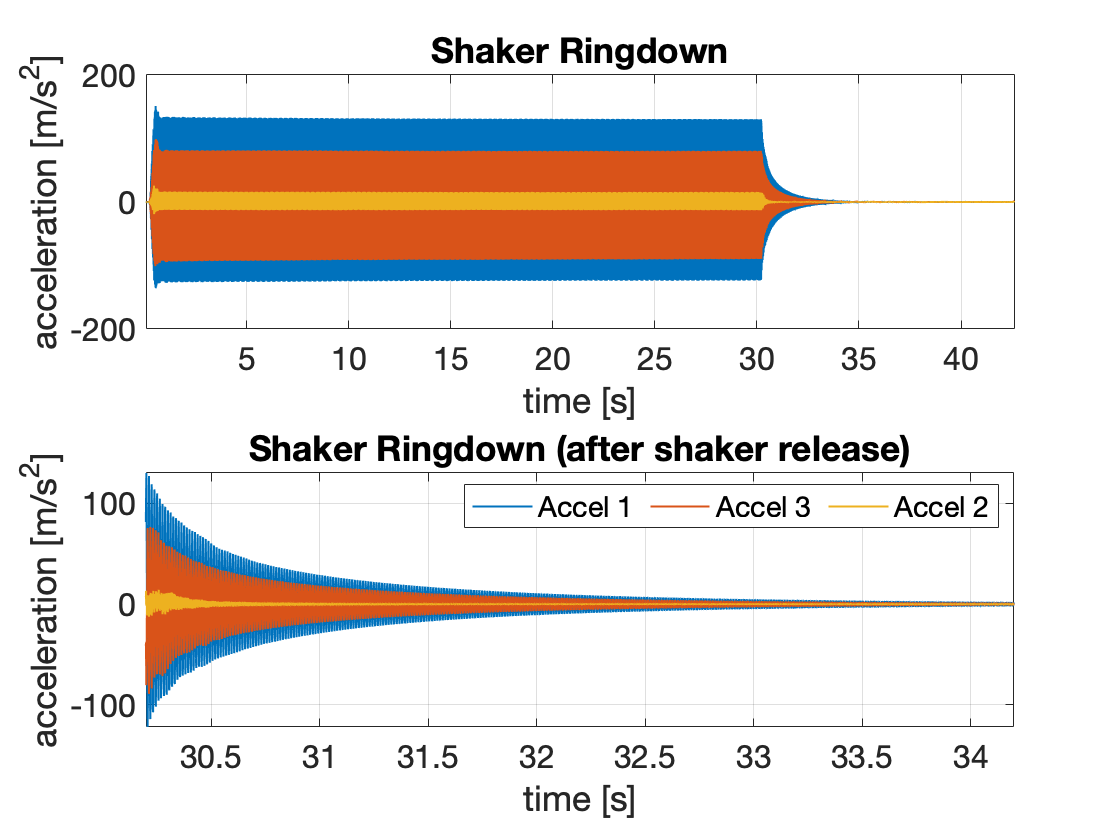

load ShakerRingdown.mat

figure;
subplot(211); hold on; grid on; box on; title('Shaker Ringdown')
plot(SRDdataAcc.time,SRDdataAcc.acc1,'Linewidth',1,'DisplayName','Accel 1')
plot(SRDdataAcc.time,SRDdataAcc.acc3,'Linewidth',1,'DisplayName','Accel 3')
plot(SRDdataAcc.time,SRDdataAcc.acc2,'Linewidth',1,'DisplayName','Accel 2')
xlabel('time [s]')
ylabel('acceleration [m/s^2]')
set(gca,'fontname',fontname)
set(gca,'fontsize',fontsize)
xlim([SRDdataAcc.time(1) SRDdataAcc.time(end) ])
subplot(212); hold on; grid on; box on; title('Shaker Ringdown (after shaker release)')
plot(SRDdataAcc.time,SRDdataAcc.acc1,'Linewidth',1,'DisplayName','Accel 1')
plot(SRDdataAcc.time,SRDdataAcc.acc3,'Linewidth',1,'DisplayName','Accel 3')
plot(SRDdataAcc.time,SRDdataAcc.acc2,'Linewidth',1,'DisplayName','Accel 2')
xlabel('time [s]')
ylabel('acceleration [m/s^2]')
set(gca,'fontname',fontname)
set(gca,'fontsize',fontsize)
xlim([30.2 34.2 ])
legend('NumColumns',3)

### Forced Frequency Responses

The dataset consists of the results from the Force Control (FC) and Response Control (RC) of TestLab for frequency response data extraction. The response is measured in co-location, so the response amplitude is that of accelerometer 3 in Fig. 1. The amplitudes of response and force are those of the fundamental harmonic of the signal and the response phase is measured with respect to the forcing signal.

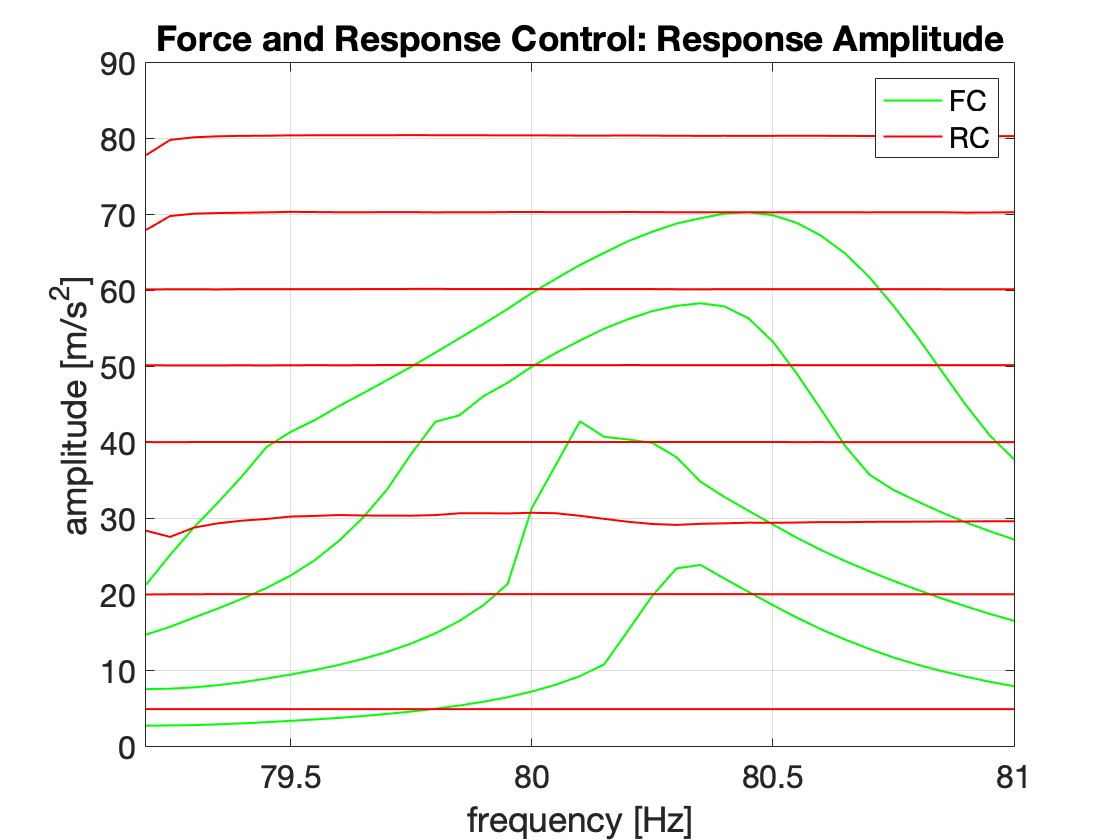

load ForcedFrequencyResponses.mat

xlimits = [79.2 81];
figure; hold on; grid on; box on;
title('Force and Response Control: Response Amplitude')
xlabel('frequency [Hz]')
ylabel('amplitude [m/s^2]')
set(gca,'fontname',fontname)
set(gca,'fontsize',fontsize)

FCdata = FRdata.ForceControl;
for ii = 1:length(FCdata)
    h = plot(FCdata(ii).frequency,FCdata(ii).amplitude,'g','Linewidth',1,'DisplayName','FC');
    if ii > 1; h.Annotation.LegendInformation.IconDisplayStyle = 'off'; end
end
RCdata = FRdata.ResponseControl;
for ii = 1:length(RCdata)
    h = plot(RCdata(ii).frequency,RCdata(ii).amplitude,'r','Linewidth',1,'DisplayName','RC');
    if ii > 1; h.Annotation.LegendInformation.IconDisplayStyle = 'off'; end
end
xlim(xlimits)
legend

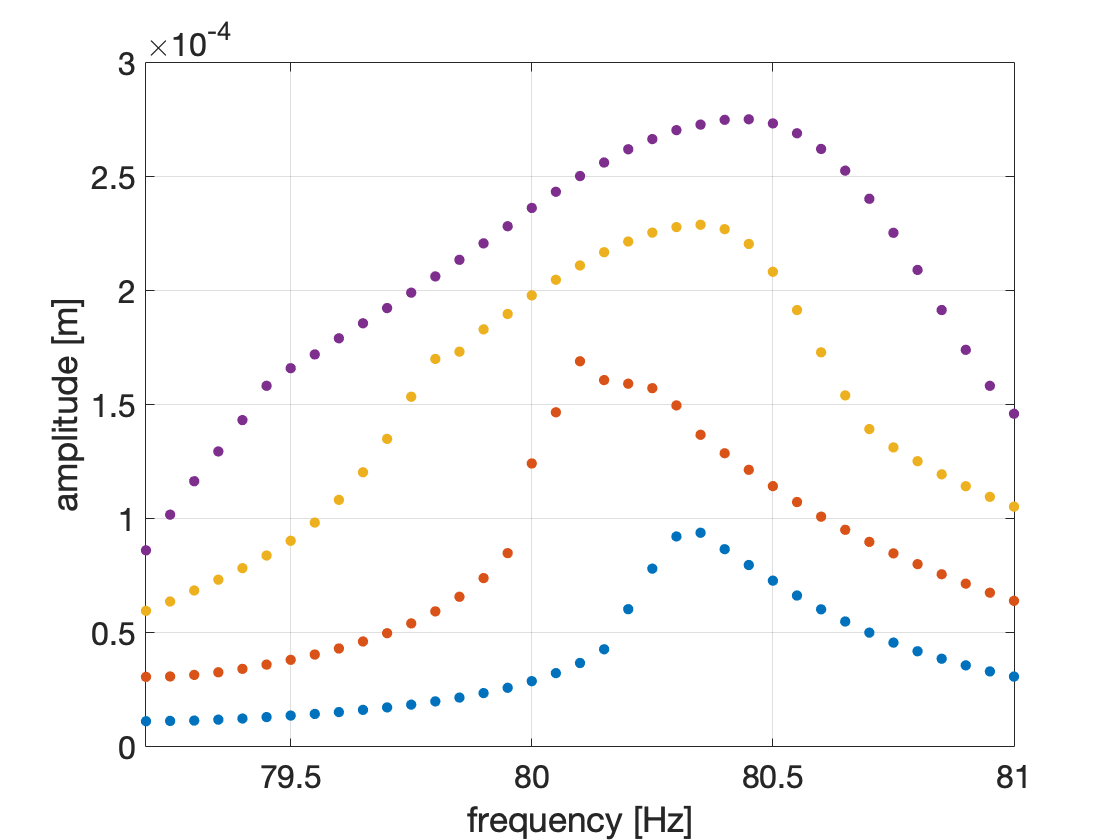


figure; hold on; grid on; box on;
xlabel('frequency [Hz]')
ylabel('amplitude [m]')
set(gca,'fontname',fontname)
set(gca,'fontsize',fontsize)

FCdata = FRdata.ForceControl;
for ii = 1:length(FCdata)
    plot(FCdata(ii).frequency,(FCdata(ii).amplitude')./((2*pi*FCdata(ii).frequency).^2),'.','MarkerSize',14)
end
RCdata = FRdata.ResponseControl;
xlim(xlimits)

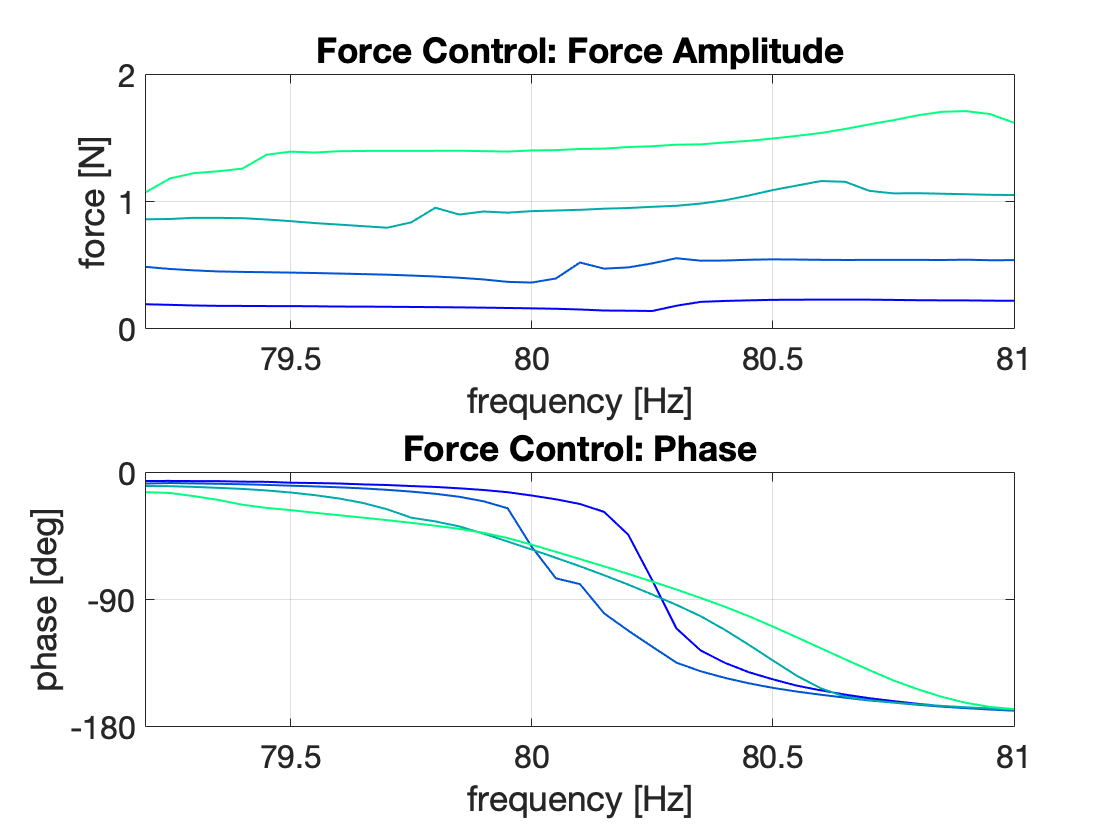


% Force Control: force and phase
figure; 
subplot(211); hold on; grid on; box on; colororder(winter(length(FCdata)))
title('Force Control: Force Amplitude')
xlabel('frequency [Hz]')
ylabel('force [N]')
set(gca,'fontname',fontname)
set(gca,'fontsize',fontsize)
xlim(xlimits)

for ii = 1:length(FCdata)
    plot(FCdata(ii).frequency,FCdata(ii).force,'Linewidth',1);
end

subplot(212); hold on; grid on; box on; colororder(winter(length(FCdata)))
title('Force Control: Phase')
xlabel('frequency [Hz]')
ylabel('phase [deg]')
set(gca,'fontname',fontname)
set(gca,'fontsize',fontsize)
xlim(xlimits)

for ii = 1:length(FCdata)
    plot(FCdata(ii).frequency,FCdata(ii).phase/pi*180,'Linewidth',1);
end
ylim([-180 0])
set(gca,'ytick',[-180 -90 0])

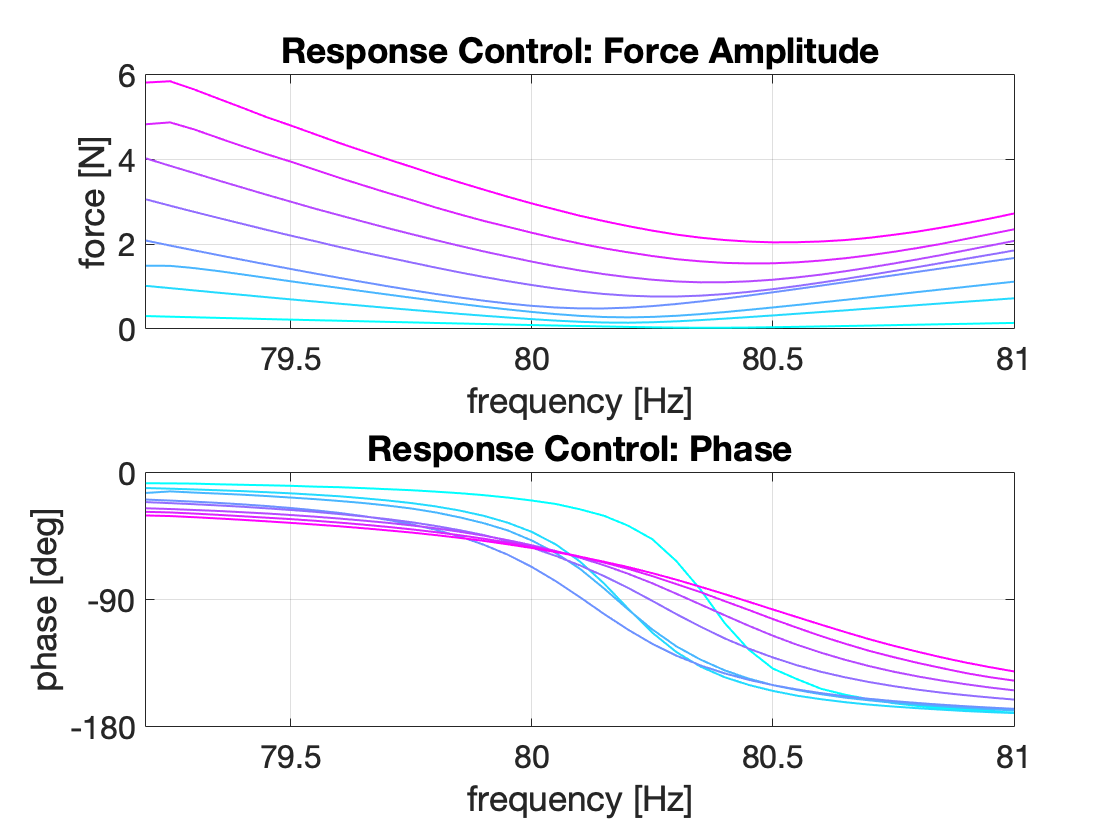


% Response Control: force and phase
figure; 
subplot(211); hold on; grid on; box on; colororder(cool(length(RCdata)))
title('Response Control: Force Amplitude')
xlabel('frequency [Hz]')
ylabel('force [N]')
set(gca,'fontname',fontname)
set(gca,'fontsize',fontsize)
xlim(xlimits)

for ii = 1:length(RCdata)
    plot(RCdata(ii).frequency,RCdata(ii).force,'Linewidth',1);
end

subplot(212); hold on; grid on; box on; colororder(cool(length(RCdata)))
title('Response Control: Phase')
xlabel('frequency [Hz]')
ylabel('phase [deg]')
set(gca,'fontname',fontname)
set(gca,'fontsize',fontsize)
xlim(xlimits)

for ii = 1:length(RCdata)
    plot(RCdata(ii).frequency,RCdata(ii).phase/pi*180,'Linewidth',1);
end
ylim([-180 0])
set(gca,'ytick',[-180 -90 0])

## DIC from High-speed camera data

The data is regards the upper and lower deflection lines of the beam, extrapolated using the software DICe from Sandia National lab. The data is also filtered around the frequency of the slowest vibration mode of the beam.

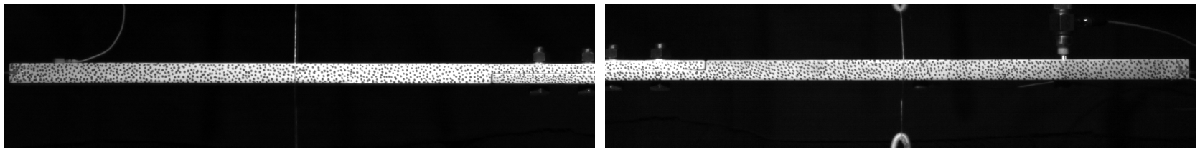

### Shaker Ringdown Testing

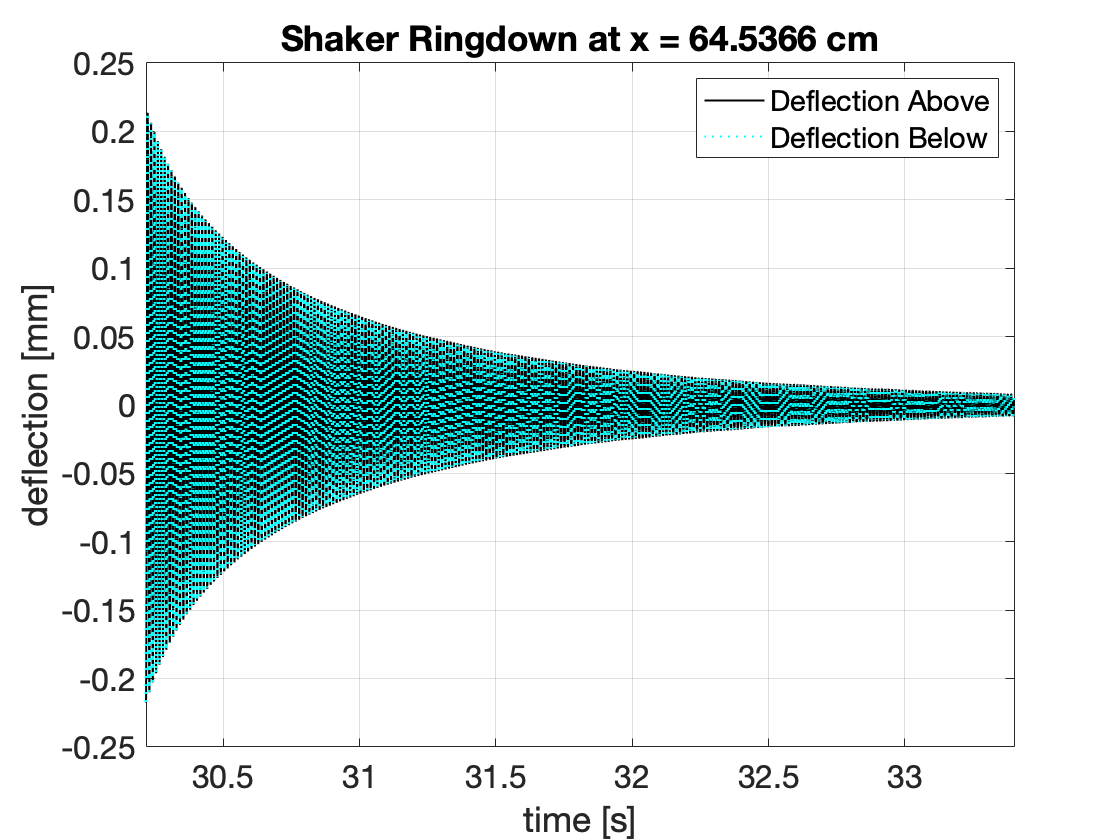

load ShakerRingdown.mat

ind_pos = 185; % Nearest Location to Accel 3
figure; hold on; grid on; box on; title(['Shaker Ringdown at x = ' num2str(SRDdataDIC.position(ind_pos)) ' cm'])
plot(SRDdataDIC.time,SRDdataDIC.deflection_above(ind_pos,:),'k','Linewidth',1,'DisplayName','Deflection Above')
plot(SRDdataDIC.time,SRDdataDIC.deflection_below(ind_pos,:),'c:','Linewidth',1,'DisplayName','Deflection Below')
xlabel('time [s]')
ylabel('deflection [mm]')
set(gca,'fontname',fontname)
set(gca,'fontsize',fontsize)
xlim([SRDdataDIC.time(1) SRDdataDIC.time(end) ])
legend

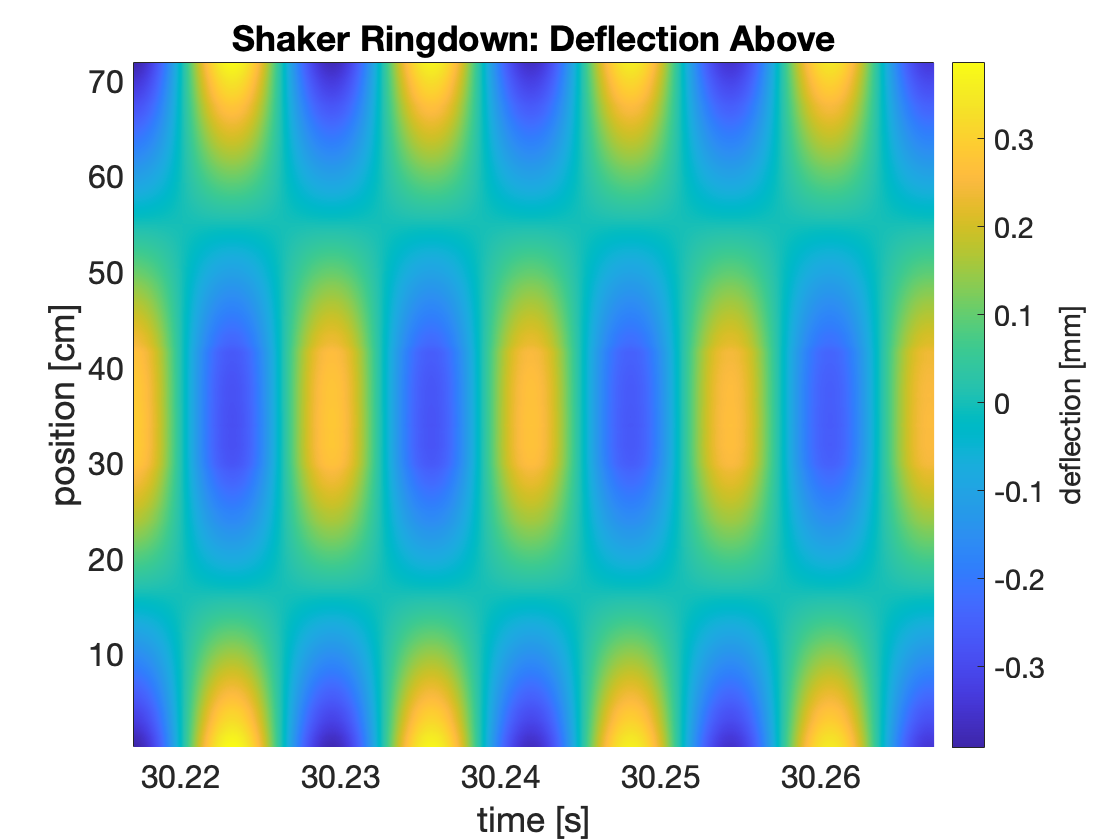


% Plot deflections for approximately the first four oscillation cycles
figure; hold on; box on; 
surf(SRDdataDIC.time,SRDdataDIC.position,SRDdataDIC.deflection_above)
shading interp
view(2)
title('Shaker Ringdown: Deflection Above')
xlabel('time [s]')
ylabel('position [cm]')
zlabel('deflection [mm]')
set(gca,'fontname',fontname)
set(gca,'fontsize',fontsize)
c = colorbar;
c.Label.String = 'deflection [mm]';
xlim(SRDdataDIC.time(1)+[0 4]/80)
ylim([SRDdataDIC.position(1) SRDdataDIC.position(end)])

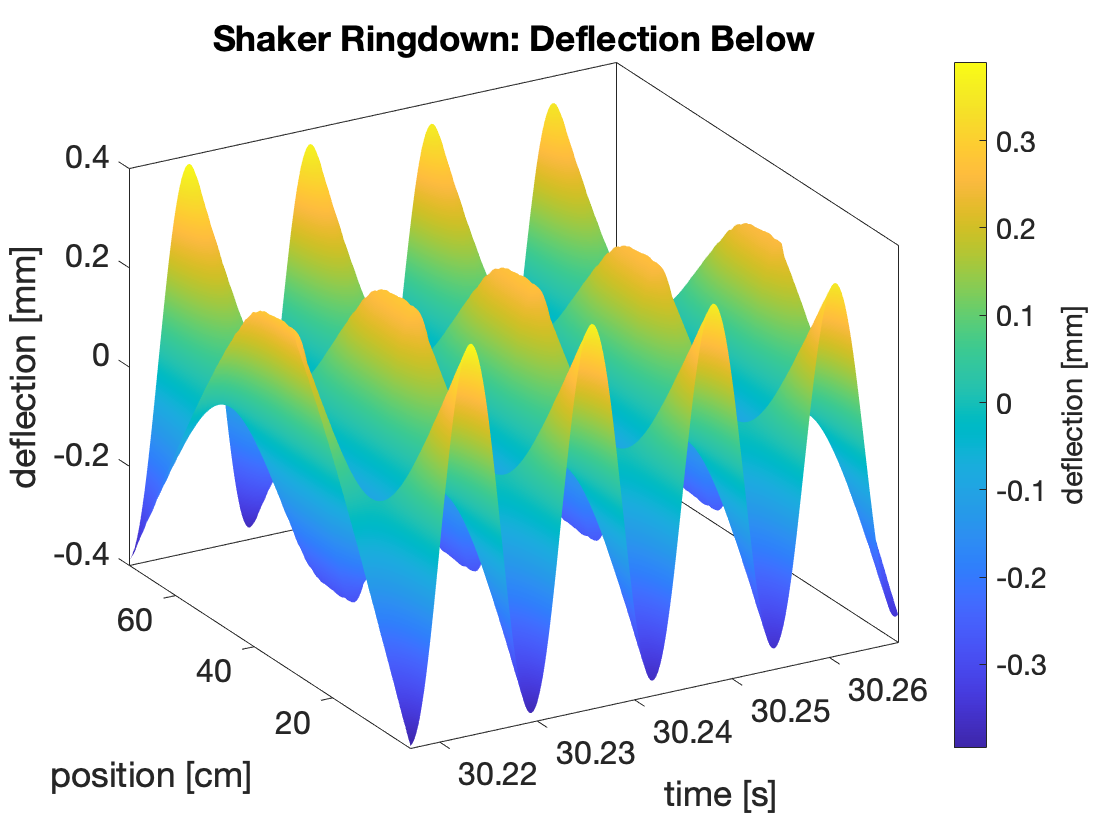


figure; hold on; box on; 
surf(SRDdataDIC.time,SRDdataDIC.position,SRDdataDIC.deflection_below)
shading interp
view(-30,28)
title('Shaker Ringdown: Deflection Below')
xlabel('time [s]')
ylabel('position [cm]')
zlabel('deflection [mm]')
set(gca,'fontname',fontname)
set(gca,'fontsize',fontsize)
c = colorbar;
c.Label.String = 'deflection [mm]';
xlim(SRDdataDIC.time(1)+[0 4]/80)
ylim([SRDdataDIC.position(1) SRDdataDIC.position(end)])